# Noise Variances

% Run script
run('Noise_estimation.m');

Launching ROS Core...
.Done in 1.8029 seconds.
Initializing ROS master on http://12.0.10.178:11311.
Initializing global node /matlab_global_node_77981 with NodeURI http://Gioels-MBP:49920/ and MasterURI http://localhost:11311.


Error using Noise_estimation
Cannot determine the message type of the /qualisys/Super_marker_1/odom topic. Either the topic is not registered with the ROS master, or the ROS master is not reachable.

Error in run (line 91)
evalin('caller', strcat(script, ';'));

# Mex functions generation

#### FORWARD KINEMATICS


$$\pmatrix{p_{1} \cr P_{2} \cr .. \cr P_{M}} = \pmatrix{\Phi_1(q) \cr \Phi_2(q) \cr ..  \cr \Phi_M(q) } \qquad \Longrightarrow \qquad  p = \Phi(q)$$


#### JACOBIAN COMPUTATION


$$\pmatrix{\dot{p}_{1} \cr \dot{p}_{2} \cr .. \cr \dot{p}_{M}} = \pmatrix{J_1(q) \cr J_2(q) \cr ..  \cr J_M(q) } \cdot \dot{q} \qquad \Longrightarrow \qquad  \tilde{u} = J(q) \cdot  \dot{q} $$


% Marker is placed in the : shoulder --> 1
%                           forearm  --> 2
%                           hand     --> 3
% Human arm parameters
% run('human_arm_param.m');
% marker.links = [1;
%                 1;
%                 1;
%                 1;
%                 2;
%                 2;
%                 2;
%                 3;
%                 3];
% 
% sample_Time = 0.01;
% % Change directory
% cd 'C code/S4_F3_H2/';
% 
% % Run script
% mex_generation(marker.links, sample_Time);
% cd ../..;

# LS APPROACH


$$\dot{q} = J^{\dagger}(q) \cdot  \tilde{u} \qquad \longrightarrow \qquad \tilde{u} = \dot{p}$$


% Clear variables
clear;
clear global;
close all;
clc;

% Human arm parameters
run('human_arm_param.m');

## 1.  PERFECT GUESS OF INITIAL CONDITION q0 

% Model IC 
q0_model = zeros(n, 1);
% LS IC
q0_LS = zeros(n, 1);

% Results
LS_KF_EKF_NLDM("LS", 'free', [], [], 'S4_F3_H2');

## 2.  WRONG GUESS OF INITIAL CONDITION q0 

% Model IC 
q0_model = zeros(n, 1);
% LS IC
q0_LS = [deg2rad(30);
         zeros(n-1, 1)];

% Results
LS_KF_EKF_NLDM("LS", 'free', [], [], 'S4_F3_H2');

# KALMAN FILTER ON LINEARIZED DISCRETE STATE-SPACE MODEL

## 1.  Discrete Non Linear model (Ts = 10ms)

Runge-Kutta discretization method is applied to the continuos NL model. The sampling time Ts = 10ms was chosen.


$$\begin{cases}
\mathbf{q}_{k+1} = \textbf{f}(\mathbf{q}_k, \mathbf{\tilde{u}}_k)   \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) 
+  \mathbf{v}_k \\
\end{cases} \qquad , \quad 

\begin{cases}
\mathbf{\tilde{u}}_k \sim \mathcal{N}(0, \mathbf{N_u})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases} \\
\textbf{f} = \mathbf{q}_k + \frac{1}{6}  \cdot T_s  \cdot (\mathbf{k_1} + 2\mathbf{k_2} + 2\mathbf{k_3} + \mathbf{k_4})
\\
\\
\mathbf{k_1} = \mathbf{J}^{\dagger}(\mathbf{q}_k)\cdot \mathbf{\tilde{u}}_k  \\
\mathbf{k_2} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  \frac{k_1}{2})\cdot \mathbf{\tilde{u}}_k  \\
\mathbf{k_3} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  \frac{k_2}{2})\cdot \mathbf{\tilde{u}_k  \\
\mathbf{k_4} = \mathbf{J}^{\dagger}(\mathbf{q}_k + T_s  \cdot  k_3)\cdot \mathbf{\tilde{u}}_k$$


The comparison between the simulation and the discrete Non Linear model is reported below.

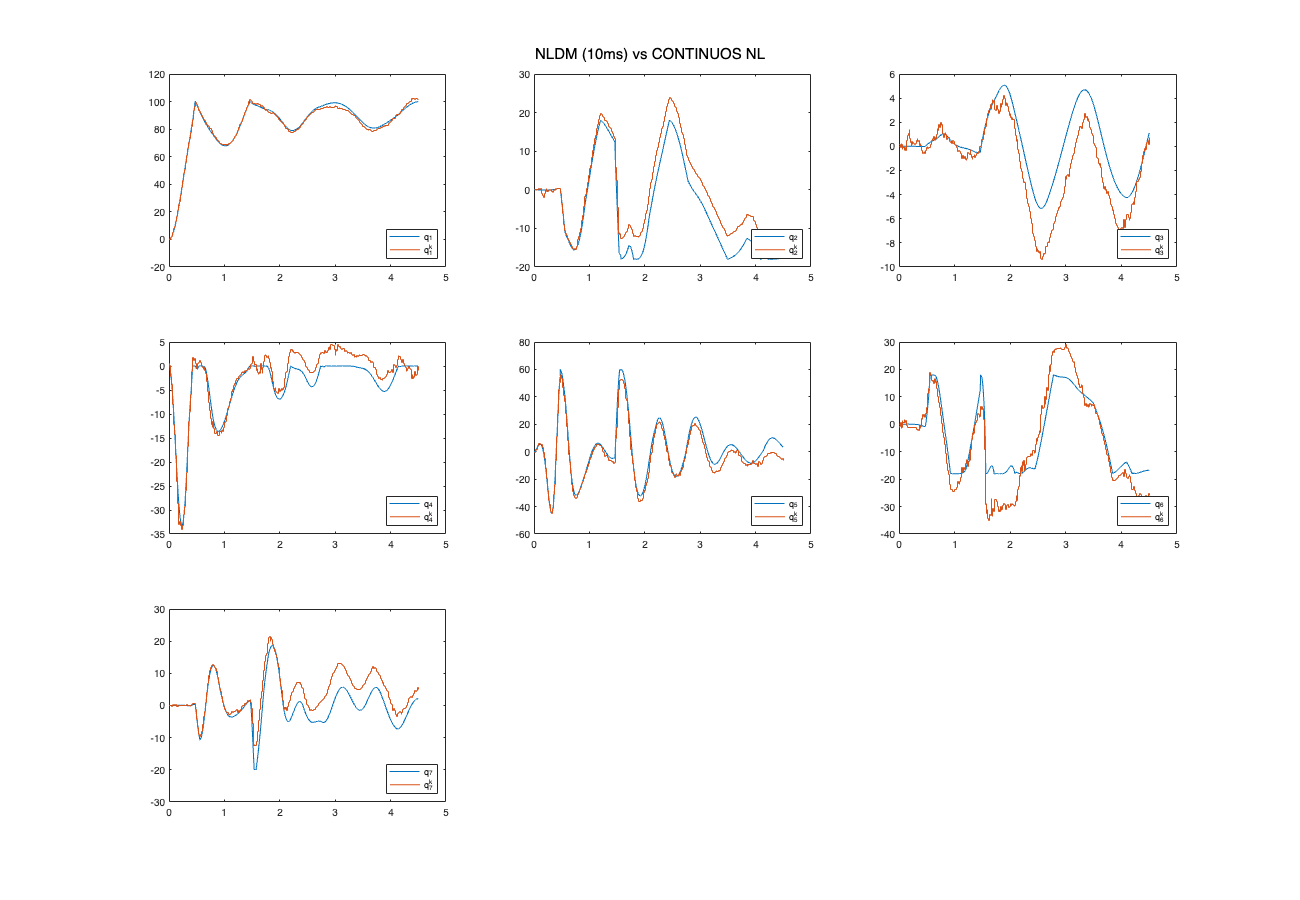

% Clear variables
clear;
clear global;
close all;
clc;

% Human arm parameters
run('human_arm_param.m');

% Model IC 
q0_model = zeros(n, 1);

% Sample time is fixed at 0.01
LS_KF_EKF_NLDM("NLDM", 'free', [], [], 'S4_F3_H2');

## 2.  Linearized Discrete model around equilibrium point

The Discrete state-space model is computed by linearizing the discrete NL model around a given equilibrium point.                                                


$$\begin{cases}
\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot \mathbf{\Delta \tilde{u}}_k  + \mathbf{w}_k \\
\mathbf{\Delta p}_k = \mathbf{H}\cdot\mathbf{\Delta q}_k  + \mathbf{v}_k\\
\end{cases} \qquad , \quad 
\begin{cases}
\mathbf{\Delta q}_{k} = \mathbf{q}_k - \mathbf{q}_{eq} \\
\mathbf{\Delta \tilde{u}}_{k} = \mathbf{\tilde{u}}_k - \mathbf{u}_{eq} \\
\mathbf{\tilde{u}}_k = \mathbf{\bar{u}}_k + \mathbf{n}_k
\end{cases} \qquad , \quad \begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


where,


$$\\
\mathbf{F} = \nabla_q\textbf{f}|_{q_{eq}, u_{eq}} \\
\mathbf{G} = \nabla_u\textbf{f}|_{q_{eq}, u_{eq}} \\
\mathbf{H} = \nabla_q\mathbf{\Phi}|_{q_{eq}}$$


## 3.  Kalman Filter on the linearized discrete state-space model

The Discrete state-space model is computed by linearizing the discrete NL model around the given equilibrium point.                                              


$$\begin{cases}
\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot \mathbf{\Delta \tilde{u}}_k  + \mathbf{w}_k \\
\mathbf{\Delta p}_k = \mathbf{H}\cdot\mathbf{\Delta q}_k  + \mathbf{v}_k\\
\end{cases} \qquad , \quad \begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


In simulink, the above state space representaion was implemented. Th considered input was  $\mathbf{\Delta \tilde{u}}_k + \mathbf{n}_k$, so that $\mathbf{\Delta q}_{k+1} = \mathbf{F}\cdot \mathbf{\Delta q}_k + \mathbf{G}\cdot (\mathbf{\Delta \tilde{u}}_k  + \mathbf{n}_k)$,            $\mathbf{n}_k \sim \mathcal{N}(0, \mathbf{N})$

The matrix $\mathbf{N}$ was computed such that $\mathbf{GNG^T} = \mathbf{Q}$

### 3.1 Free fall motion, eq. point (q_eq = 0, u_eq = 0)

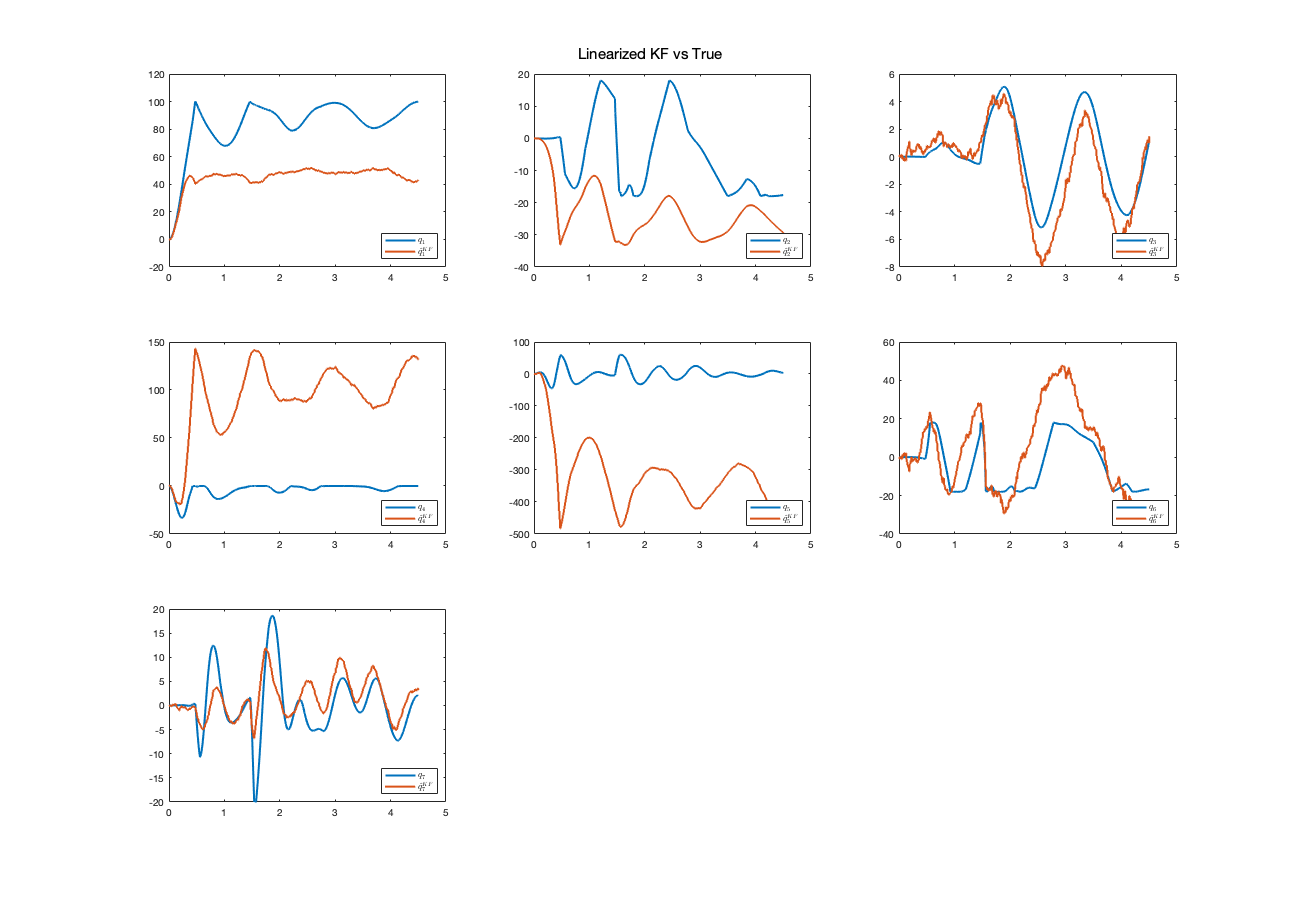

% Clear variables
clear;
clear global;
close all;
clc;

% Human arm parameters
run('human_arm_param.m');

% Model IC
q0_model = zeros(n, 1);

% Equilibrium point
kf.q_eq = zeros(n, 1);
kf.u_eq = zeros(3*m, 1);

% Initial estimate Delta_q0
kf.Delta_q0 = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 10 * eye(n);

% Results
LS_KF_EKF_NLDM("KF", 'free', marker, number_samples, 'S4_F3_H2');

### 3.2 Human arm motion close to the rest position

The discrete NL model is now linearized around the rest position of the human arm, i.e. when the human arm is perpendicular to the ground.

In this context all initial joints' variables are assumed to be set to 0°, except for $q_1$ which is set to 87°.


$$q_0 = \pmatrix{87\degree  \cr 0\degree  \cr ..  \cr 0\degree } , \qquad q_{eq} =  \pmatrix{90 \degree  \cr 0\degree  \cr ..  \cr 0\degree },  \qquad u_{eq} =  \pmatrix{ 0  \cr 0  \cr ..  \cr 0 } $$


The model is now expected to simulate better the human arm motion.

The comparison between simulation and linearized discrete state-space is reported below.

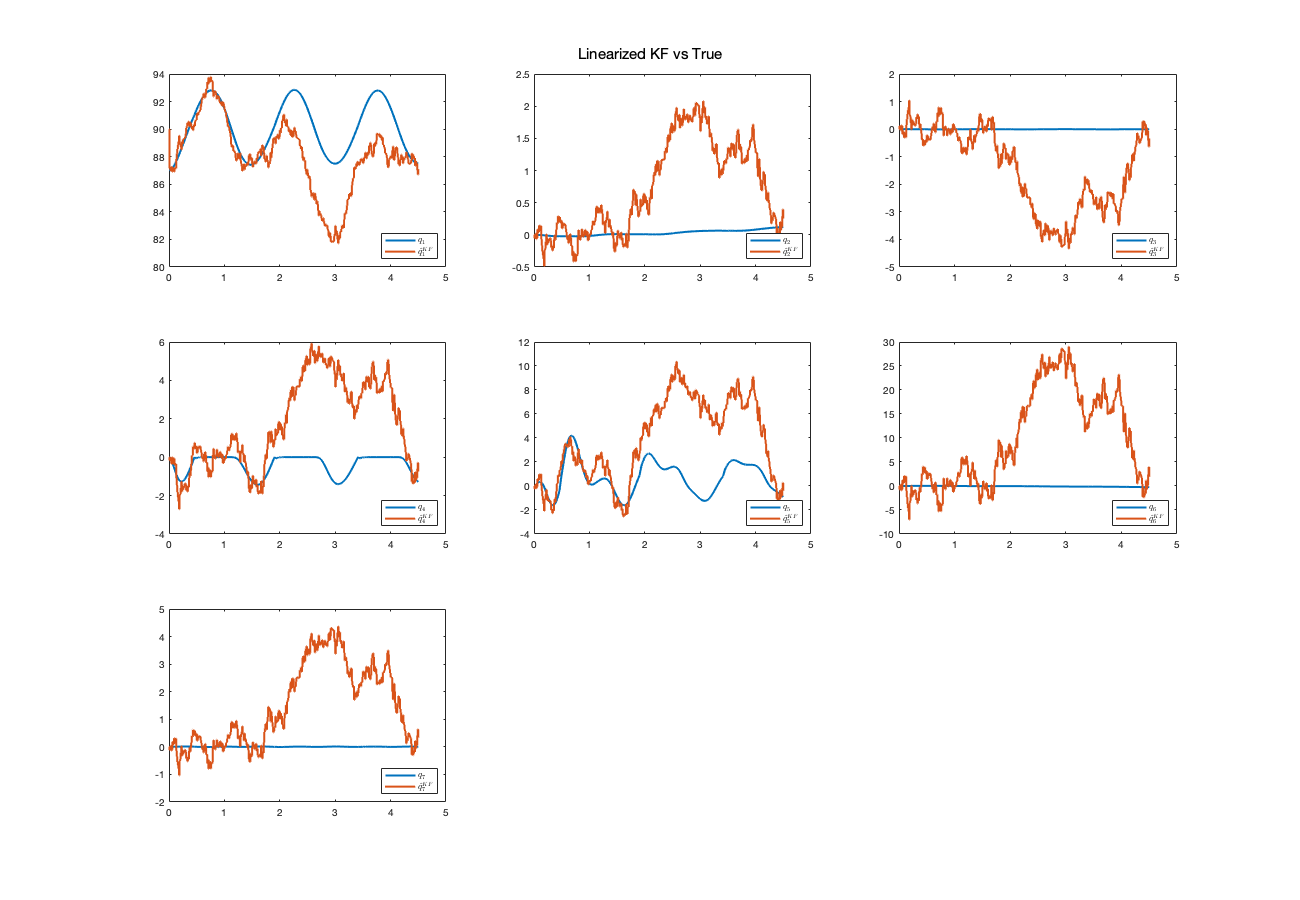

% Model IC
q0_model = [deg2rad(87); zeros(n-1, 1)];

% Equilibrium point
kf.q_eq = [pi/2; zeros(n-1, 1)];
kf.u_eq = zeros(3*m, 1);

% Initial estimate Delta_q0
kf.Delta_q0 = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 10 * eye(n);

% Results
LS_KF_EKF_NLDM("KF", 'free', marker, number_samples, 'S4_F3_H2');

# EXTENDED KALMAN FILTER

## 1.  Discrete Non Linear model


$$\begin{cases}
\mathbf{q}_{k} = \textbf{f}(\mathbf{q}_{k-1}, \mathbf{u}_{k-1}) + \mathbf{w}_{k-1}  \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) + \mathbf{v}_k \\
\end{cases}  \qquad , \quad 
\begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


We perform a Taylor series expansion of the state equation around $\mathbf{q}_{k-1} = \hat{\mathbf{q}}_{k-1}^+$ and we obtain:


$$\mathbf{q}_{k} = \mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^+, \mathbf{u}_{k-1}\right) + \left.\frac{\partial \mathbf{f}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}}\left(\mathbf{q}_{k-1}-\hat{\mathbf{q}}_{k-1}^{+}\right) + \mathbf{w}_{k-1} \\ =
\mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}\right)+\mathbf{F}_{k-1}\left(\mathbf{q}_{k-1}-\hat{\mathbf{q}}_{k-1}^{+}\right) + \mathbf{w}_{k-1} \\ =

\mathbf{F}_{k-1} \mathbf{q}_{k-1}+\left[\mathbf{f}\left(\hat{\mathbf{q}}_{k-1}^{+}, \mathbf{u}_{k-1}\right)-\mathbf{F}_{k-1} \hat{\mathbf{q}}_{k-1}^{+}\right] + \mathbf{w}_{k-1} \\ =
\mathbf{F}_{k-1} \mathbf{q}_{k-1}+\mathbf{r}_{k-1}+\mathbf{w}_{k-1}$$


We linearize the measurement equation around $\mathbf{q}_k = \hat{\mathbf{q}}_k^-$ and we obtain:


$$\mathbf{p}_{k} = \mathbf{\Phi}\left(\hat{\mathbf{q}}_k^-\right) + \left.\frac{\partial \mathbf{\Phi}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k}^{-}}\left(\mathbf{q}_{k}-\hat{\mathbf{q}}_{k}^{-}\right)+ \mathbf{v}_{k} \\ =

\mathbf{\Phi}\left(\hat{\mathbf{q}}_k^-\right) + \mathbf{H}_{k}\left(\mathbf{q}_{k}-\hat{\mathbf{q}}_{k}^{-}\right)+ \mathbf{v}_{k} \\ =

\mathbf{H}_{k}\mathbf{q}_{k}+\left[\mathbf{\Phi}\left(\hat{\mathbf{q}}_{k}^{-}\right)-\mathbf{H}_{k}\hat{\mathbf{q}}_{k}^{-}\right]+\mathbf{v}_k \\ =
\mathbf{H}_{k} \mathbf{q}_{k}+\mathbf{z}_{k}+\mathbf{v}_{k}$$
				

We can use the standard Kalman Filter equations to estimate the state.

In summary, the following steps are performed to compute the KF estimate at each step.

- The system and measurement equations are given as follows 

          
$$\begin{cases}
\mathbf{q}_{k} = \textbf{f}(\mathbf{q}_{k-1}, \mathbf{u}_{k-1}) + \mathbf{w}_{k-1}  \\
\mathbf{p}_k = \mathbf{\Phi}(\mathbf{q}_k) + \mathbf{v}_k \\
\end{cases}  \qquad , \quad 
\begin{cases}
\mathbf{w}_k \sim \mathcal{N}(0, \mathbf{Q})\\
\mathbf{v}_k \sim \mathcal{N}(0, \mathbf{R})
\end{cases}$$


- Initialize the filter as follows  $\hat{\mathbf{q}}_{0}^+ = \mathbb{E}(\mathbf{q}_0) \quad, \quad
\mathbf{P}_0^+ = \mathbb{E}[(\mathbf{q}_0 - \hat{\mathbf{q}}_{0}^+)(\mathbf{q}_0 - \hat{\mathbf{q}}_{0}^+)^T]$ 

- For k = 1, 2, .. perform the following 

                          
$$\mathbf{F}_{k-1} =  \left.\frac{\partial \mathbf{f}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k-1}^{+},\mathbf{u}_{k-1}
$$


                            **TIME UPDATE**

                            
$$\mathbf{P}_k^- = \mathbf{F}_{k-1}\mathbf{P}_{k-1}^+\mathbf{F}_{k-1}^T + \mathbf{Q} \\
\hat{\mathbf{q}}_k^- = \mathbf{f}(\hat{\mathbf{q}}_{k-1}^+, \mathbf{u}_{k-1})$$


                             
$$\mathbf{H}_{k} =  \left.\frac{\partial \mathbf{\Phi}}{\partial \mathbf{q}}\right|_{\hat{\mathbf{q}}_{k}^{-}$$


                            **MEASUREMENT UPDATE**

                            
$$\mathbf{K}_k = \mathbf{P}_{k}^-\mathbf{H}_{k}^T(\mathbf{H}_k\mathbf{P}_k^-\mathbf{H}_k^T + \mathbf{R})^{-1}
\\
\hat{\mathbf{q}}_k^+ = \hat{\mathbf{q}}_k^- + \mathbf{K}_k[\textbf{p}_k - \mathbf{\Phi}(\hat{\mathbf{q}}_k^-)]
\\
\mathbf{P}_k^+ = (\mathbf{I} - \mathbf{K}_k\mathbf{H}_k)\mathbf{P}_k^-$$


A new example is now considered.

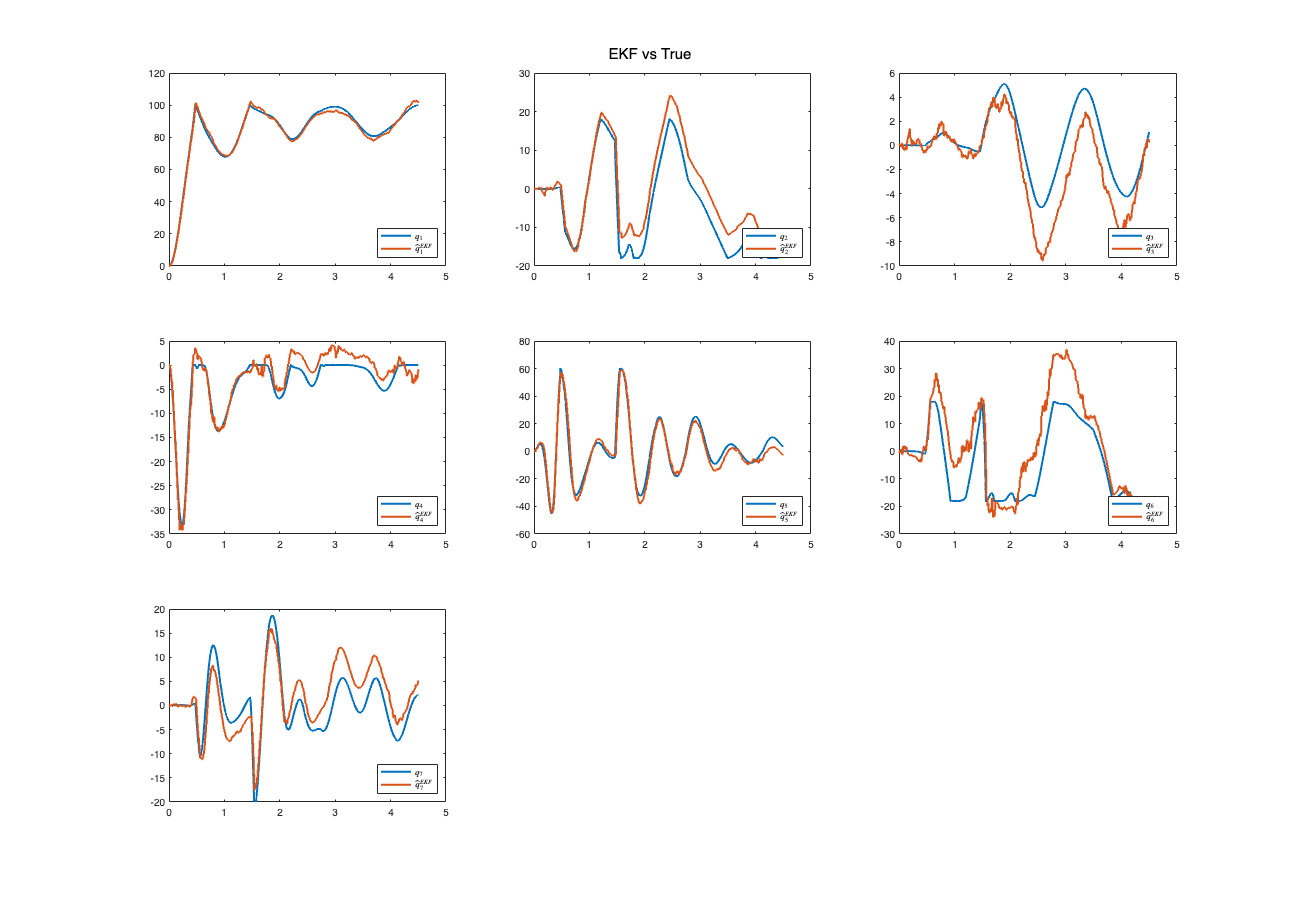

% Clear variables
clear;
clear global;
close all;
clc;

% Human arm parameters
run('human_arm_param.m');

% Model IC
q0_model = [deg2rad(0); zeros(n-1, 1)];

% Initial estimate q0
ekf.q0 = zeros(n, 1);

% Initial covariance estimate P0
ekf.P0 = 10 * eye(n);

% Results
LS_KF_EKF_NLDM("EKF", 'free', marker, number_samples, 'S4_F3_H2');

# Comparison between Methods

% Clear variables
clear;
clear global;
close all;
clc;

% Human arm parameters
run('human_arm_param.m');

% Model IC 
q0_model = zeros(n, 1);

## LS

% LS IC
q0_LS = zeros(n, 1);

## KF

% Equilibrium point
kf.q_eq = [pi/2; zeros(n-1, 1)];
kf.u_eq = zeros(3*m, 1);

% Initial estimate Delta_q0
kf.Delta_q0 = zeros(n, 1);

% Initial covariance estimate P0
kf.P0 = 10 * eye(n);

## EKF

% Initial estimate q0
ekf.q0 = zeros(n, 1);

% Initial covariance estimate P0
ekf.P0 = 10 * eye(n);


## Results

   1.0e-10 *

    1.0000         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0
         0         0    1.0000         0         0         0         0
         0         0         0    1.0000         0         0         0
         0         0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0    1.0000



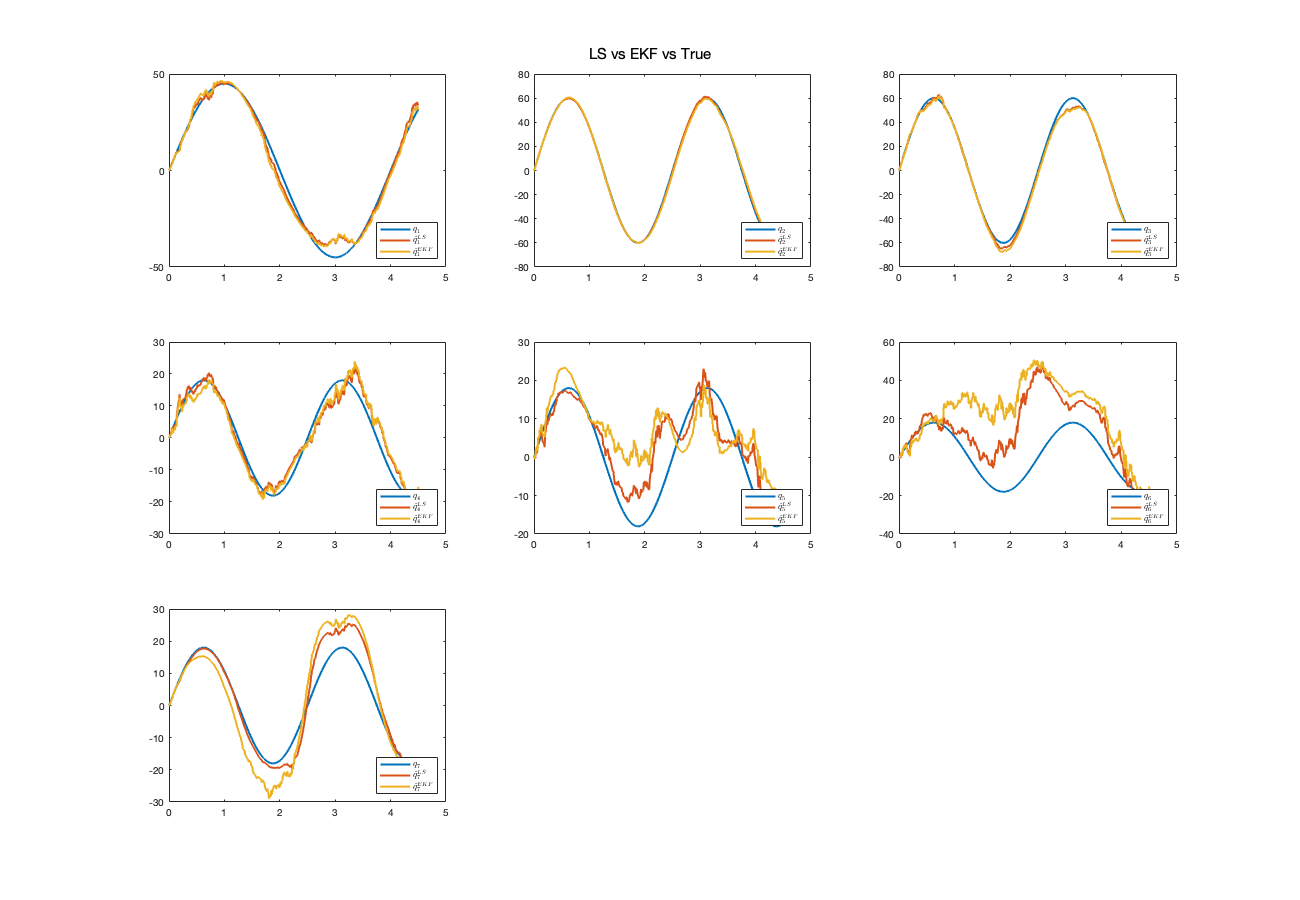

noise.Q =  0.0000000001 * diag(ones(n, 1));
LS_KF_EKF_NLDM(["EKF", "LS"], 'precompiuted', marker, number_samples, 'S4_F3_H2');

    10     0     0     0     0     0     0
     0    10     0     0     0     0     0
     0     0    10     0     0     0     0
     0     0     0    10     0     0     0
     0     0     0     0    10     0     0
     0     0     0     0     0    10     0
     0     0     0     0     0     0    10



noise.Q =  10 * diag(ones(n, 1));
LS_KF_EKF_NLDM(["EKF", "LS"], 'precompiuted', marker, number_samples, 'S4_F3_H2');